## Лаба 6. Критерий Найквиста и системы с запаздыванием

### Задание 3. Запаздывание

p = 1; q = 4; n = 4; m = 1; j = 2;
s = tf('p');

### Объект W3

***Случай tau = 0***

count = 1;

simTimeStart = 0;
simTimeEnd = 50;
dt = 0.02;
t_sim = simTimeStart:dt:simTimeEnd;

tau = 0;
W1 = exp(-tau*s)*(7*s+5)/(s^2 +4*s);
W1_closed = feedback(W1,1);

%%% АФЧХ %%%
figure;
nyquist(W1)
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, \tau  = ', num2str(tau)), 'Interpreter', 'tex')

save_file("nyquist_task31_object"+count);

%%% АЧХ-ФЧХ %%%
freqs = linspace(0, 5, 2000);
omega = 2*pi*freqs;
[mag, phase, ~] = bode(W1, omega); % omega is in rad/s
mag = squeeze(mag); % Magnitude (absolute, not dB)
phase = squeeze(phase); % Phase (degrees)

%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W1_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce31_closed"+count);

***Случай tau = 0.1***

tau = 0.1;
W1 = exp(-tau*s)*(7*s+5)/(s^2 +4*s);
W1_closed = feedback(W1,1);

figure;
nyquist(W1)
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, \tau  = ', num2str(tau)), 'Interpreter', 'tex')
save_file("nyquist_task32_object"+count);

%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W1_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce32_closed"+count);

***Случай tau = 0.3 ***

tau = 0.3;
W1 = exp(-tau*s)*(7*s+5)/(s^2 +4*s);
W1_closed = feedback(W1,1);
figure;
nyquist(W1)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, \tau  = ', num2str(tau)), 'Interpreter', 'tex')
save_file("nyquist_task33_object"+count);

%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W1_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce33_closed"+count);

***Случай tau = 0.5***

%%% АФЧХ %%%
tau = 0.5;
W1 = exp(-tau*s)*(7*s+5)/(s^2 +4*s);
W1_closed = feedback(W1,1);
figure;
nyquist(W1)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, \tau  = ', num2str(tau)), 'Interpreter', 'tex')
save_file("nyquist_task34_object"+count);

%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W1_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce34_closed"+count);

***Случай tau = 5***

%%% АФЧХ %%%
tau = 5;
W1 = exp(-tau*s)*(7*s+5)/(s^2 +4*s);
W1_closed = feedback(W1,1);
figure;
nyquist(W1)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, \tau  = ', num2str(tau)), 'Interpreter', 'tex')
save_file("nyquist_task35_object"+count);

%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W1_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce35_closed"+count);

%%% АФЧХ %%%

% tau = 2.5;
% W1 = exp(-tau*s)*(7*s+5)/(s^2 +4*s);
% W1_closed = feedback(W1,1);
% figure;
% nyquist(W1)
% % grid on;
% xlabel('Magnitude (dB)');
% ylabel('Phase (degrees)');
% title(strcat('АФЧХ, \tau  = ', num2str(tau)), 'Interpreter', 'tex')
% save_file("nyquist_task35_object"+count);

tau = 0;
W1 = exp(-tau*s)*(7*s+5)/(s^2 +4*s);
figure;
h = bodeplot(W1)
grid on;
h.showCharacteristic('AllStabilityMargins');
save_file("log_nyquist_task3_object"+count);

allmargin(W1)

### Объект W4

***Случай tau = 0***

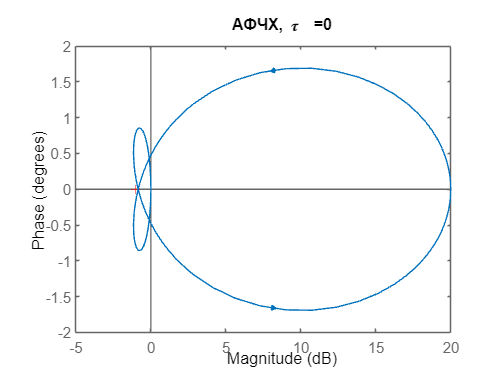

count = 2;
s = tf('p');
simTimeStart = 0;
simTimeEnd = 300;
dt = 0.02;
t_sim = simTimeStart:dt:simTimeEnd;

tau = 0;
W2 = exp(-tau*s)*(20*s^2 + 1.6*s + 2)/(10*s^3 - 10*s^2 -0.1*s + 0.1);
W2_closed = feedback(W2,1);

%%% АФЧХ %%%
figure;
nyquist(W2)
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, \tau  = ', num2str(tau)), 'Interpreter', 'tex')

save_file("nyquist_task31_object"+count);

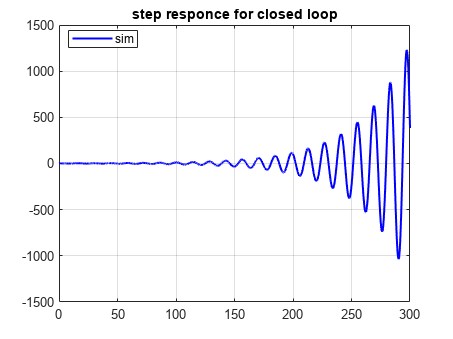


%%% АЧХ-ФЧХ %%%
freqs = linspace(0, 5, 2000);
omega = 2*pi*freqs;
[mag, phase, ~] = bode(W2, omega); % omega is in rad/s
mag = squeeze(mag); % Magnitude (absolute, not dB)
phase = squeeze(phase); % Phase (degrees)

%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W2_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce31_closed"+count);

***Случай tau = 0.1***

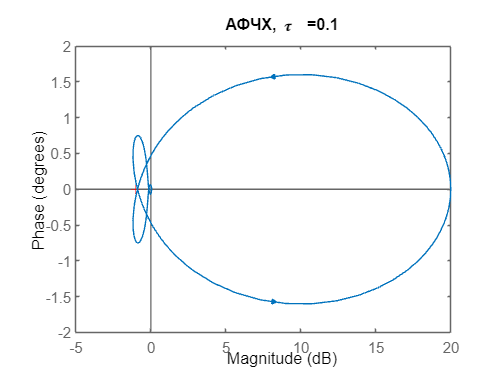

tau = 0.1;
W2 = exp(-tau*s)*(20*s^2 + 1.6*s + 2)/(10*s^3 -10*s^2 -0.1*s + 0.1);
W2_closed = feedback(W2,1);

figure;
nyquist(W2)
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, \tau  = ', num2str(tau)), 'Interpreter', 'tex')
save_file("nyquist_task32_object"+count);

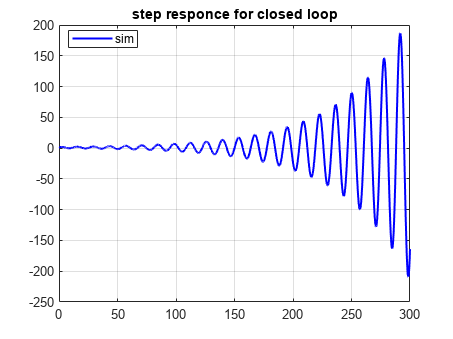


%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W2_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce32_closed"+count);

***Случай tau = 0.2***

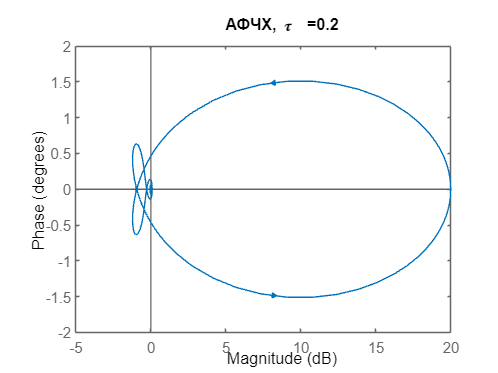

tau = 0.2;
W2 = exp(-tau*s)*(20*s^2 + 1.6*s + 2)/(10*s^3 -10*s^2 -0.1*s + 0.1);
W2_closed = 1/(1+W2);

figure;
nyquist(W2)
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, \tau  = ', num2str(tau)), 'Interpreter', 'tex')
save_file("nyquist_task33_object"+count);

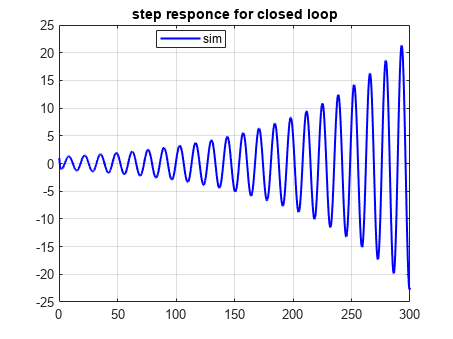


%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W2_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce33_closed"+count);

***Случай tau = 0.3 ***

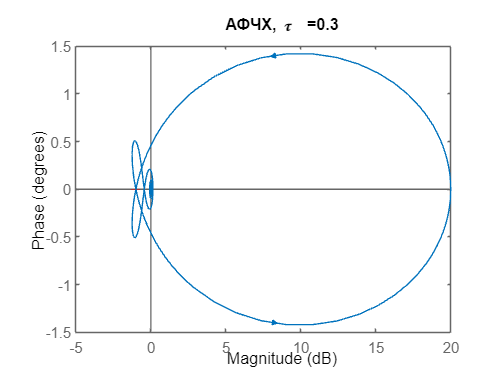

tau = 0.3;
W2 = exp(-tau*s)*(20*s^2 + 1.6*s + 2)/(10*s^3 -10*s^2 -0.1*s + 0.1);
W2_closed = 1/(1+W2);
figure;
nyquist(W2)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, \tau  = ', num2str(tau)), 'Interpreter', 'tex')
save_file("nyquist_task34_object"+count);

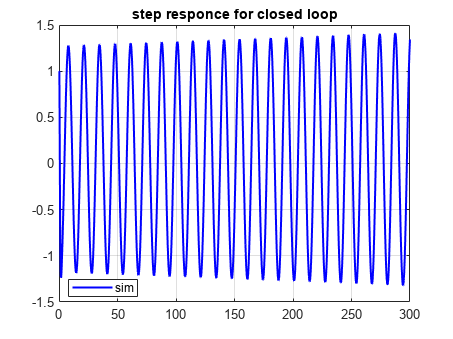


%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W2_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce34_closed"+count);

***Случай tau = 0.4 ***

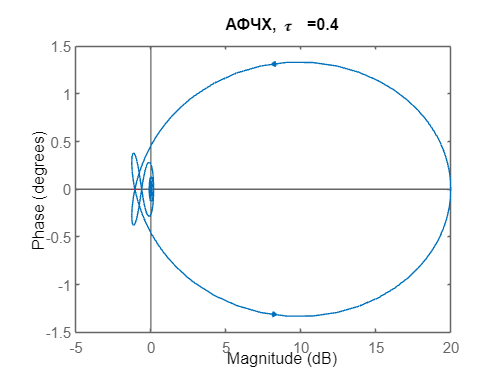

tau = 0.4;
W2 = exp(-tau*s)*(20*s^2 + 1.6*s + 2)/(10*s^3 -10*s^2 -0.1*s + 0.1);
W2_closed = 1/(1+W2);
figure;
nyquist(W2)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, \tau  = ', num2str(tau)), 'Interpreter', 'tex')
save_file("nyquist_task35_object"+count);

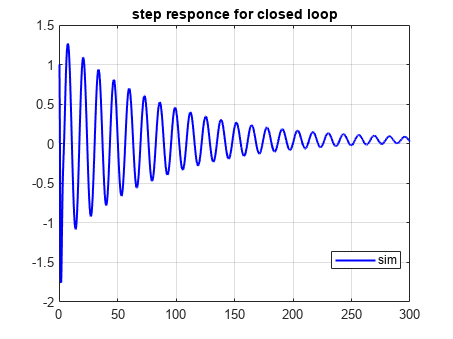


%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W2_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce35_closed"+count);

***Случай tau = 0.5***

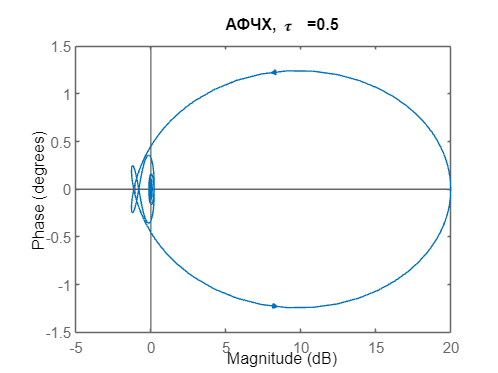

%%% АФЧХ %%%
tau = 0.5;
W2 = exp(-tau*s)*(20*s^2 + 1.6*s + 2)/(10*s^3 -10*s^2 -0.1*s + 0.1);
W2_closed = feedback(W2,1);
figure;
nyquist(W2)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, \tau  = ', num2str(tau)), 'Interpreter', 'tex')
save_file("nyquist_task36_object"+count);

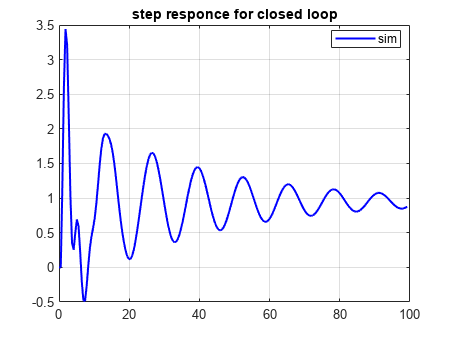


%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W2_closed, 100);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce36_closed"+count);


w2o = @(t) tf([10, -6, 11],[10, -1, 38, 20], 'InputDelay', t);
ss = tf("s");
w2c = @(t) (10*ss^2-6*ss+11)/(10*ss^3 + (10*exp(-t*ss)-1)*ss^2 + (38-6*exp(-t*ss))*ss + (20+11*exp(-t*ss)) )*exp(-t*ss);


***Случай tau = 0.55***

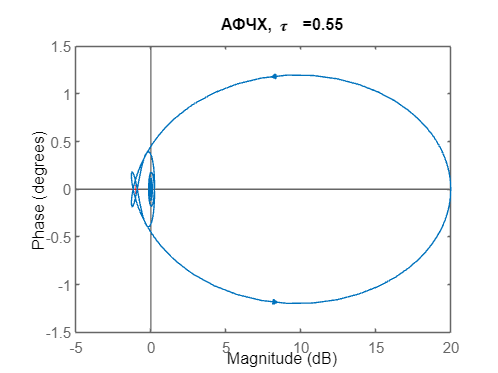

%%% АФЧХ %%%
tau = 0.55;
W2 = exp(-tau*s)*(20*s^2 + 1.6*s + 2)/(10*s^3 -10*s^2 -0.1*s + 0.1);
W2_closed = 1/(1+W2);
figure;
nyquist(W2)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, \tau  = ', num2str(tau)), 'Interpreter', 'tex')
save_file("nyquist_task37_object"+count);

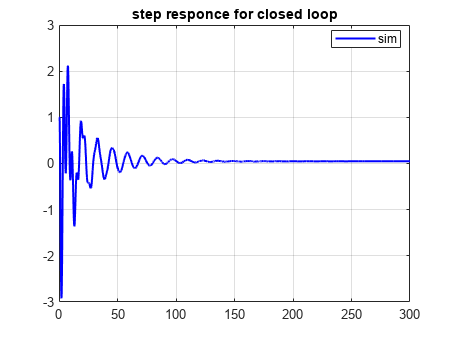


%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W2_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce37_closed"+count);

***Случай tau = 0.7***

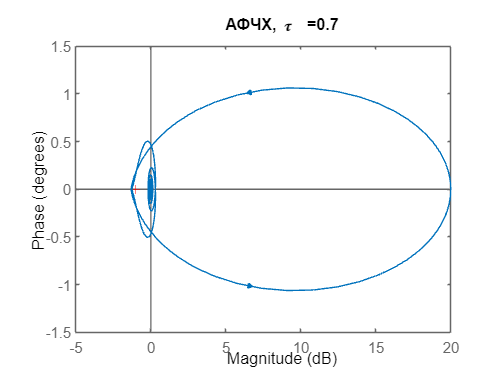

%%% АФЧХ %%%
tau = 0.7;
W2 = exp(-tau*s)*(20*s^2 + 1.6*s + 2)/(10*s^3 -10*s^2 -0.1*s + 0.1);
W2_closed = feedback(W2,1);
figure;
nyquist(W2)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, \tau  = ', num2str(tau)), 'Interpreter', 'tex')
save_file("nyquist_task38_object"+count);

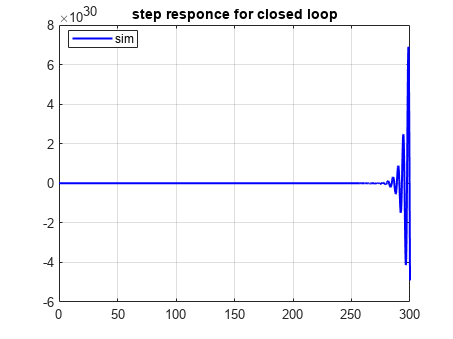


%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W2_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce38_closed"+count);

***Случай tau = 5***

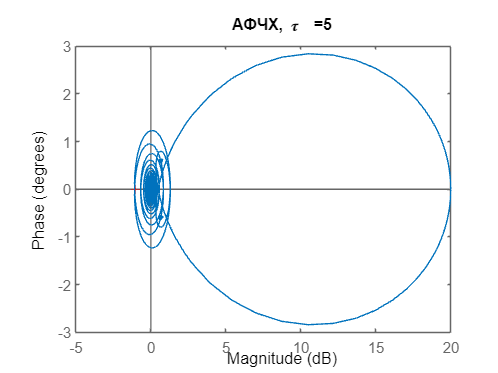

%%% АФЧХ %%%
tau = 5;
W2 = exp(-tau*s)*(20*s^2 + 1.6*s + 2)/(10*s^3 -10*s^2 -0.1*s + 0.1);
W2_closed = feedback(W2,1);
figure;
nyquist(W2)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, \tau  = ', num2str(tau)), 'Interpreter', 'tex')
save_file("nyquist_task39_object"+count);

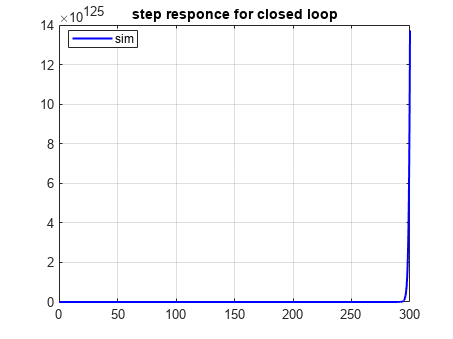


%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W2_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce39_closed"+count);

***Случай tau = 10***

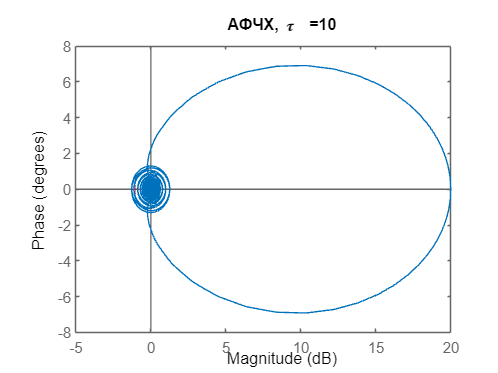

%%% АФЧХ %%%
tau = 10;
W2 = exp(-tau*s)*(20*s^2 + 1.6*s + 2)/(10*s^3 -10*s^2 -0.1*s + 0.1);
W2_closed = feedback(W2,1);
figure;
nyquist(W2)
% grid on;
xlabel('Magnitude (dB)');
ylabel('Phase (degrees)');
title(strcat('АФЧХ, \tau  = ', num2str(tau)), 'Interpreter', 'tex')
save_file("nyquist_task310_object"+count);

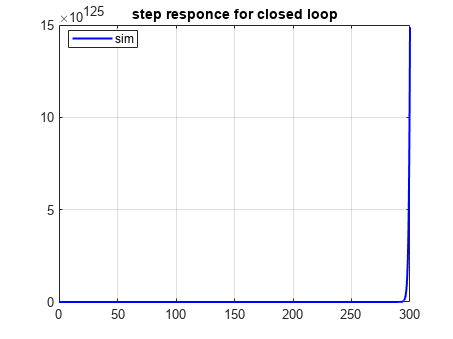


%%% Переходные функции %%%
figure;
[y_sim, t_out] = step(W2_closed, t_sim);
plot(t_out, y_sim, 'b', 'LineWidth', 1.5);
grid on
title('step responce for closed loop')
legend('sim', 'Location', 'best')
save_file("step_responce310_closed"+count);

tau = 0;
W2 = exp(-tau*s)*(20*s^2 + 1.6*s + 2)/(10*s^3 -10*s^2 -0.1*s + 0.1);
figure;
h = bodeplot(W2)


h =

	resppack.bodeplot



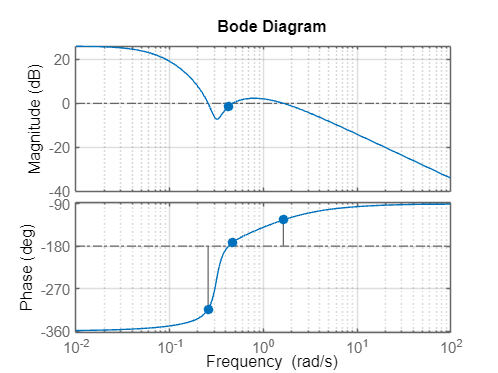

grid on;
h.showCharacteristic('AllStabilityMargins');
save_file("log_nyquist_task3_object"+count);


allmargin(W2)

ans = struct with fields:
     GainMargin: 1.1875
    GMFrequency: 0.4243
    PhaseMargin: [-134.0431 8.2678 55.7286]
    PMFrequency: [0.2576 0.4727 1.6401]
    DelayMargin: [15.3070 0.3053 0.5930]
    DMFrequency: [0.2576 0.4727 1.6401]
         Stable: 0


## Функции

**Save file in the folder**

function save_file(name)
    path = 'D:\Math\control_theory\linear_systems_labs\lab6\latex6\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');
end

**Рисовать комплексные числа**

function plotComplexRoots(roots)
    % Input: 'roots' is a vector containing up to 5 complex numbers.
    
    % Ensure the figure is properly configured
    figure;
    hold on;
    grid on;
    axis equal;
    title(' ');
    xlabel('Re', 'Interpreter', 'latex');
    ylabel('Imag', 'Interpreter', 'latex');
    
    % Define colors for up to 5 roots
    colors = {'r', 'g', 'b', 'm', 'c'};
    
    % Plot each root with unique color and LaTeX label
    for i = 1:min(length(roots), 5)
        plot(real(roots(i)), imag(roots(i)), 'o', ...
            'MarkerSize', 6, 'MarkerFaceColor', colors{i}, ...
            'DisplayName', ['$\lambda_' num2str(i) '$']);
    end
    
    % Compute limits with offset for better visibility
    real_vals = real(roots);
    imag_vals = imag(roots);
    real_min = min(real_vals) - 5;
    real_max = max(real_vals) + 5;
    imag_min = min(imag_vals) - 5;
    imag_max = max(imag_vals) + 5;
    
    % Set axis limits
    xlim([real_min, real_max]);
    ylim([imag_min, imag_max]);
    
    % Add a vertical magenta line at x = 0
    xline(0, 'm--', 'LineWidth', 1.5, 'DisplayName','vertical');
    
    % Add a legend with LaTeX interpreter
    legend('Interpreter', 'latex', 'Location', 'best');
    
    hold off;
end

% 
% simTimeStart = 0;
% simTimeEnd = 5;
% 
% l1 = -2 + 3j; l2 = -2 - 3j; l3= -10;
% out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));
% t = out.simout.Time;
% y_out = out.simout.Data; g_show = ones(1, length(t))'; 
% 
% h = figure; set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% subplot(2,1,1);
% plot(t, y_out, 'r');
% title('output');   
% xlabel('time [s]');                  
% ylabel('f(t)');                      
% grid on;
% legend('y(t)');
% 
% subplot(2,1,2);
% plotComplex(l1,l2,l3)
% save_file(h, 'output_task3_exp12')
% 
% % Вычисление стационарного значения
% y_final = y_out(end);
% % перерегулирование по стандартной формуле
% y_max = max(y_out);
% overshoot = ((y_max - y_final) / y_final) * 100
% % Время, когда функция достигает 98% от конечного значения
% threshold = 0.99 * y_final; 
% transient_time = t( find(y_out >= threshold, 1) )